# Actividad 2: Análisis de transformaciones

Ana Itzel Hernández García A01737526

**Obtener** los vectores de velocidades lineal y angular para las siguientes configuraciones

**Obtener** las matrices de transformación homogéneas locales y globales de cada configuración y realizar un análisis comparativo.

:

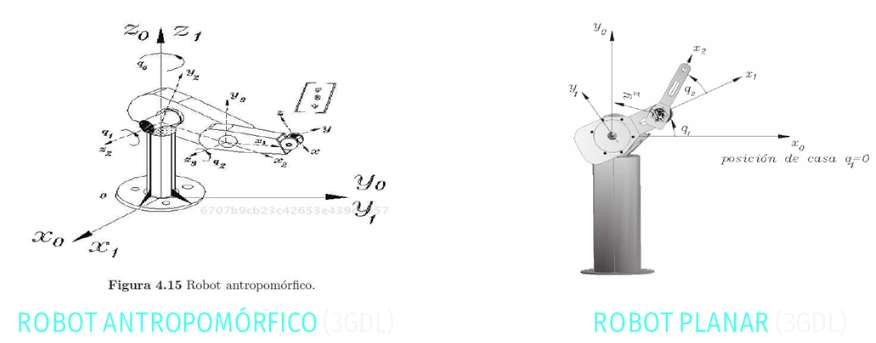

Limpieza de pantalla/ entorno

clear all
close all
clc

## **Declaración de variables**

syms th1(t) l1 
syms th2(t) l2   
syms th3(t) l3

Configuración del robot (**0** para junta **rotacional**, 1 para junta prismatica)

RP=[0 0 0];

Creamos el vector de coordenadas generalizadas

Q = [th1 th2 th3];
disp('Coordenadas generalizadas'); Q

Coordenadas generalizadas


$$Q(t) = \left(\begin{array}{ccc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) & {\mathrm{th}}_{3}\left(t\right) \end{array}\right)$$

Creamos el vector de velocidades generalizadas

Qp = diff(Q, t);
disp('Velocidades generalizadas'); Qp

Velocidades generalizadas


$$Qp(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) \end{array}\right)$$

Grados de libertad del robot

GDL = size(RP,2); 
GDL_str = num2str(GDL);

## Robot planar

### Articulación 1 (Planar)

Posición de la junta 1 respecto a 0

P_P(:,:,1) = [l1*cos(th1);
             l1*sin(th1); %Vector de posición indexado por página
             0];

Matriz de rotación de la junta 1 respecto a 0

R_P(:,:,1) = [cos(th1) -sin(th1) 0;
             sin(th1)  cos(th1) 0; %Análisis del robot pendulo
               0         0     1];

### Articulación 2 (Planar)

Posición de la junta 2 respecto a 1

P_P(:,:,2) = [l2*cos(th2);
             l2*sin(th2); %Vector de posición indexado por página
             0];

Matriz de rotación de la junta 2 respecto a 1

R_P(:,:,2) = [cos(th2) -sin(th2) 0;
             sin(th2)  cos(th2) 0; %Análisis del robot pendulo
               0         0     1];

### Articulación 3 (Planar)

Posición de la junta 3 respecto a 2

P_P(:,:,3) = [l3*cos(th3);
             l3*sin(th3); %Vector de posición indexado por página
             0];

Matriz de rotación de la junta 3 respecto a 2

R_P(:,:,3) = [cos(th3) -sin(th3) 0;
             sin(th3)  cos(th3) 0; %Análisis del robot pendulo
               0         0     1];

## Robot antropomorfico

Matriz de rotación al rededor de z 

rotacion_z = [cos(th1) -sin(th1) 0;
              sin(th1)  cos(th1) 0;
                 0         0     1];

Matriz de la rotación con los 90 grados positivos (Evaluación con respecto al ángulo)


$$\mathrm{Rotación}\;z\;a\;x=\;\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(90\right) & -\sin \left(90\right)\\
0 & \sin \left(90\right) & \cos \left(90\right)
\end{array}\right\rbrack$$


x_transfor = [1 0 0;
              0 0 -1;
              0 1 0];

Transformación es la rotación por la evaluación en 90°

transfor_1 = rotacion_z *x_transfor;

### Articulación 1 (antropomorfico)

Posición de la junta 1 respecto a 2

P_A(:,:,1) = [0;
             0;
             l1]; % L1 es la distancia de z a la articulación 1

Matriz de rotación de la junta 1 a 2

R_A(:,:,1) = transfor_1;

### Articulación 2 (antropomorfico)

Posición de la atriculación 2 a 3

P_A(:,:,2) = [l2*cos(th2); 
             l2*sin(th2); 
             0]; 

Matriz de rotación de la junta 2 a 3

R_A(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0            0     1];

### Articulación 3

Posición de la atriculación 3 respecto a la 2

P_A(:,:,3) = [l3*cos(th3); 
            l3*sin(th3); 
            0]; 

Matriz de rotación de la junta 3 a respecto a 2 0°

R_A(:,:,3) = [cos(th3) -sin(th3) 0;
            sin(th3)  cos(th3) 0;
            0            0     1];

## Matrices

%Creamos un vector de ceros 
Vector_Zeros = zeros(1,3);

### Robot planar

Inicializamos las matrices de transformaciones homogéneas locales

A_P(:,:,GDL) = simplify([R_P(:,:,GDL) P_P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las matrices de transformaciones homogéneas globales

T_P(:,:,GDL) = simplify([R_P(:,:,GDL) P_P(:,:,GDL); Vector_Zeros 1]);

Inicializamos los vectoresde posición vistos desde el marco de referencia inical

POP(:,:,GDL) = P_P(:,:,GDL);

Inicializamos los matrices de rotación vistos desde el marco de referencia inical

ROP(:,:,GDL) = R_P(:,:,GDL);

### Robot antropomorfico

Inicializamos las matrices de transformaciones homogéneas locales

A_A(:,:,GDL) = simplify([R_A(:,:,GDL) P_A(:,:,GDL); Vector_Zeros 1]);

Inicializamos las matrices de transformaciones homogéneas globales

T_A(:,:,GDL) = simplify([R_A(:,:,GDL) P_A(:,:,GDL); Vector_Zeros 1]);

Inicializamos los vectoresde posición vistos desde el marco de referencia inical

POA(:,:,GDL) = P_A(:,:,GDL);

Inicializamos los matrices de rotación vistos desde el marco de referencia inical

ROA(:,:,GDL) = R_A(:,:,GDL);

for i = 1: GDL
    i_str = num2str(i);

    %Locales
    disp(strcat('Matriz de Transformación(PLANAR) local A', i_str));
    A_P(:,:,i) = simplify([R_P(:,:,i) P_P(:,:,i); Vector_Zeros 1]);
    A_P(:,:,i)
    disp(strcat('Matriz de Transformación (ANTROPOMOTFICO) local A', i_str));
    A_A(:,:,i) = simplify([R_A(:,:,i) P_A(:,:,i); Vector_Zeros 1]);
    A_A(:,:,i)

    %Globales
    try 
        T_P(:,:,i) = T_P(:,:,i-1) * A_P(:,:,i);
        T_A(:,:,i) = T_A(:,:,i-1) * A_A(:,:,i);
    catch
        T_P(:,:,i) = A_P(:,:,i);  %Cao especifico cuando i=1
        T_A(:,:,i) = A_A(:,:,i);  %Cao especifico cuando i=1
    end
    disp(strcat('Matriz de transformación (PLANAR) global T', i_str));
    T_P(:,:,i) = simplify(T_P(:,:,i));
    T_P(:,:,i)
    disp(strcat('Matriz de transformación (ANTROPOMORFICO) global T', i_str));
    T_A(:,:,i) = simplify(T_A(:,:,i));
    T_A(:,:,i)

    %Obtenemos la matriz de rotación "RO" y el vector de traslación PO de la matriz de transformación homogenéa global 
    ROP(:,:,i) = T_P(1:3, 1:3, i);
    POP(:,:,i) = T_P(1:3, 4, i);
    %Obtenemos la matriz de rotación "RO" y el vector de traslación PO de la matriz de transformación homogenéa global 
    ROA(:,:,i) = T_A(1:3, 1:3, i);
    POA(:,:,i) = T_A(1:3, 4, i);

    disp(strcat('Matriz de rotación (PLANAR) RO', i_str));
    ROP(:,:,i)
    disp(strcat('Matriz de rotación (ANTROPOMORFICO) RO', i_str));
    ROA(:,:,i)
    disp(strcat('Vector de traslación (PLANAR) PO', i_str));
    POP(:,:,i)
    disp(strcat('Vector de traslación (ANTROPOMORFICO) PO', i_str));
    POA(:,:,i)
end

Matriz de Transformación(PLANAR) local A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación (ANTROPOMOTFICO) local A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación (PLANAR) global T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación (ANTROPOMORFICO) global T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de rotación (PLANAR) RO1


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Matriz de rotación (ANTROPOMORFICO) RO1


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$

Vector de traslación (PLANAR) PO1


$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

Vector de traslación (ANTROPOMORFICO) PO1


$$ans = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

Matriz de Transformación(PLANAR) local A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación (ANTROPOMOTFICO) local A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación (PLANAR) global T2


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

Matriz de transformación (ANTROPOMORFICO) global T2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de rotación (PLANAR) RO2


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Matriz de rotación (ANTROPOMORFICO) RO2


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 \end{array}\right)$$

Vector de traslación (PLANAR) PO2


$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

Vector de traslación (ANTROPOMORFICO) PO2


$$ans = \left(\begin{array}{c} l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) \end{array}\right)$$

Matriz de Transformación(PLANAR) local A3


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación (ANTROPOMOTFICO) local A3


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación (PLANAR) global T3


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\sigma_{2}+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\sigma_{1}+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

Matriz de transformación (ANTROPOMORFICO) global T3


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \sin\left(\sigma_{2}\right) & \cos\left(\sigma_{2}\right) & 0 & l_{1}+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sin\left(\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\cos\left(\sigma_{2}\right)\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

Matriz de rotación (PLANAR) RO3


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Matriz de rotación (ANTROPOMORFICO) RO3


$$ans = \begin{array}{l} \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sigma_{1} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

Vector de traslación (PLANAR) PO3


$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

Vector de traslación (ANTROPOMORFICO) PO3


$$ans = \left(\begin{array}{c} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\right)\\ l_{1}+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}\right)$$

### Calculamos el jacobiano lineal y angular de forma analítica

Inicializamos jacobianos analíticos 

Jv_a_P(:,GDL) = POP(:,:,GDL);
Jw_a_P(:,GDL) = POP(:,:,GDL); %Angular

Jv_a_A(:,GDL) = POA(:,:,GDL);
Jw_a_A(:,GDL) = POA(:,:,GDL); %Angular

for k = 1:GDL
    if ((RP(k)==0) | (RP(k)==1)) %Casos: articulación rotacional y prismatica

        %Para articulaciones rotacionales
        try
            Jv_a_P(:,k) = cross(ROP(:,3,k-1), POP(:,:, GDL)- POP(:,:, k-1));
            Jw_a_P(:,k) = ROP(:,3,k-1);
            Jv_a_A(:,k) = cross(ROA(:,3,k-1), POA(:,:, GDL)- POA(:,:, k-1));
            Jw_a_A(:,k) = ROA(:,3,k-1);
        catch
            Jv_a_P(:,k) = cross([0,0,1], POP(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la matriz identidad, la posición previa tambien sera 0
            Jw_a_P(:,k) = [0 ,0, 1]; %Si no hay matriz de rotación previa se obtiene la matrizde identidad
            Jv_a_A(:,k) = cross([0,0,1], POA(:,:,GDL)); 
            Jw_a_A(:,k) = [0 ,0, 1];
        end

    elseif (RP(K) == 1) %Casos: articulaciones prismáticas
        try
            Jv_a_P(:,k) = ROP(:,3,k-1);
            Jv_a_A(:,k) = ROA(:,3,k-1);
        catch
            Jv_a_P(:,k) = [0, 0, 1]; %Si no hay matriz de rotación previa se obtiene de la matriz identidad
            Jv_a_A(:,k) = [0, 0, 1];
        end
            Jw_a_P(:,k) = [0, 0, 0];
            Jw_a_A(:,k) = [0, 0, 0];
    end
end

### Despliegue

Jv_a_P = simplify(Jv_a_P);
Jw_a_P = simplify(Jw_a_P);
Jv_a_A = simplify(Jv_a_A);
Jw_a_A = simplify(Jw_a_A);
disp('Jacobiano lineal obtenido de forma analitica (PLANAR)');Jv_a_P

Jacobiano lineal obtenido de forma analitica (PLANAR)


$$Jv\_a\_P = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-\sigma_{1}-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sigma_{1}-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sigma_{1}\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{2}+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \sigma_{2}+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=l_{3}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

disp('Jacobiano lineal obtenido de forma analitica (ANTROPOMORFICO)');Jv_a_A

Jacobiano lineal obtenido de forma analitica (ANTROPOMORFICO)


$$Jv\_a\_A = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & -l_{3}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & -l_{3}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}\\ 0 & \sigma_{1} & l_{3}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sigma_{3}\\ \sigma_{3}=\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

disp('Jacobiano ángular obtenido de forma analitica (PLANAR)');Jw_a_P

Jacobiano ángular obtenido de forma analitica (PLANAR)


$$Jw\_a\_P = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

disp('Jacobiano ángular obtenido de forma analitica (ANTROPOMORFICO)');Jw_a_A

Jacobiano ángular obtenido de forma analitica (ANTROPOMORFICO)


$$Jw\_a\_A = \left(\begin{array}{ccc} 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 1 & 0 & 0 \end{array}\right)$$

VP = simplify(Jv_a_P*Qp');
VA = simplify(Jv_a_A*Qp');
disp('Velocidad líneal obtenida mediante el Jacobiano líneal (PLANAR)'); VP

Velocidad líneal obtenida mediante el Jacobiano líneal (PLANAR)


$$VP(t) = \begin{array}{l} \left(\begin{array}{c} -\sigma_{4}\,\left(l_{3}\,\sin\left(\sigma_{1}\right)+l_{2}\,\sin\left(\sigma_{2}\right)\right)-\sigma_{5}\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\sin\left(\sigma_{1}\right)+l_{2}\,\sin\left(\sigma_{2}\right)\right)-l_{3}\,\sigma_{3}\,\sin\left(\sigma_{1}\right)\\ \sigma_{4}\,\left(l_{3}\,\cos\left(\sigma_{1}\right)+l_{2}\,\cos\left(\sigma_{2}\right)\right)+\sigma_{5}\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{3}\,\cos\left(\sigma_{1}\right)+l_{2}\,\cos\left(\sigma_{2}\right)\right)+l_{3}\,\sigma_{3}\,\cos\left(\sigma_{1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\\ \sigma_{2}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{4}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{5}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}$$

disp('Velocidad líneal obtenida mediante el Jacobiano líneal(ANTROPOMORFICO)'); VA

Velocidad líneal obtenida mediante el Jacobiano líneal(ANTROPOMORFICO)


$$VA(t) = \begin{array}{l} \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-\sigma_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}-l_{3}\,\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{6}\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-\sigma_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}-l_{3}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{6}\\ \sigma_{2}\,\sigma_{3}+l_{3}\,\sigma_{1}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{3}=l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sigma_{5}\\ \sigma_{4}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sigma_{6}\\ \sigma_{5}=\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{6}=\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

WP = simplify(Jw_a_P*Qp');
WA = simplify(Jw_a_A*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular (PLANAR)'); WP

Velocidad angular obtenida mediante el Jacobiano angular (PLANAR)


$$WP(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)} \end{array}\right)$$

disp('Velocidad angular obtenida mediante el Jacobiano angular (ANTROPOMORFICA)'); WA

Velocidad angular obtenida mediante el Jacobiano angular (ANTROPOMORFICA)


$$WA(t) = \left(\begin{array}{c} \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}\right)$$